## **Driver test program to check Clothoids library**

**Triangles**

x0 = 0; y0 = 2;
x1 = 4; y1 = 3.5;
x2 = 6; y2 = 1;

T1 = Triangle2D( x0, y0, x1, y1, x2, y2 );

figure('Position',[ 1 1 800 800]);

T1.isInside(x0,y0)

ans = int64
   0


T1.isInside((x0+x1+x2)/3,(y0+y1+y2)/3)

ans = int64
   1


T1.isInside(10,20)

ans = int64
   -1



x = -10:0.05:10;
y = -5:0.05:15;
[X,Y] = meshgrid(x,y);

tic
  Z = T1.isInside(X,Y);
toc

Elapsed time is 0.016181 seconds.


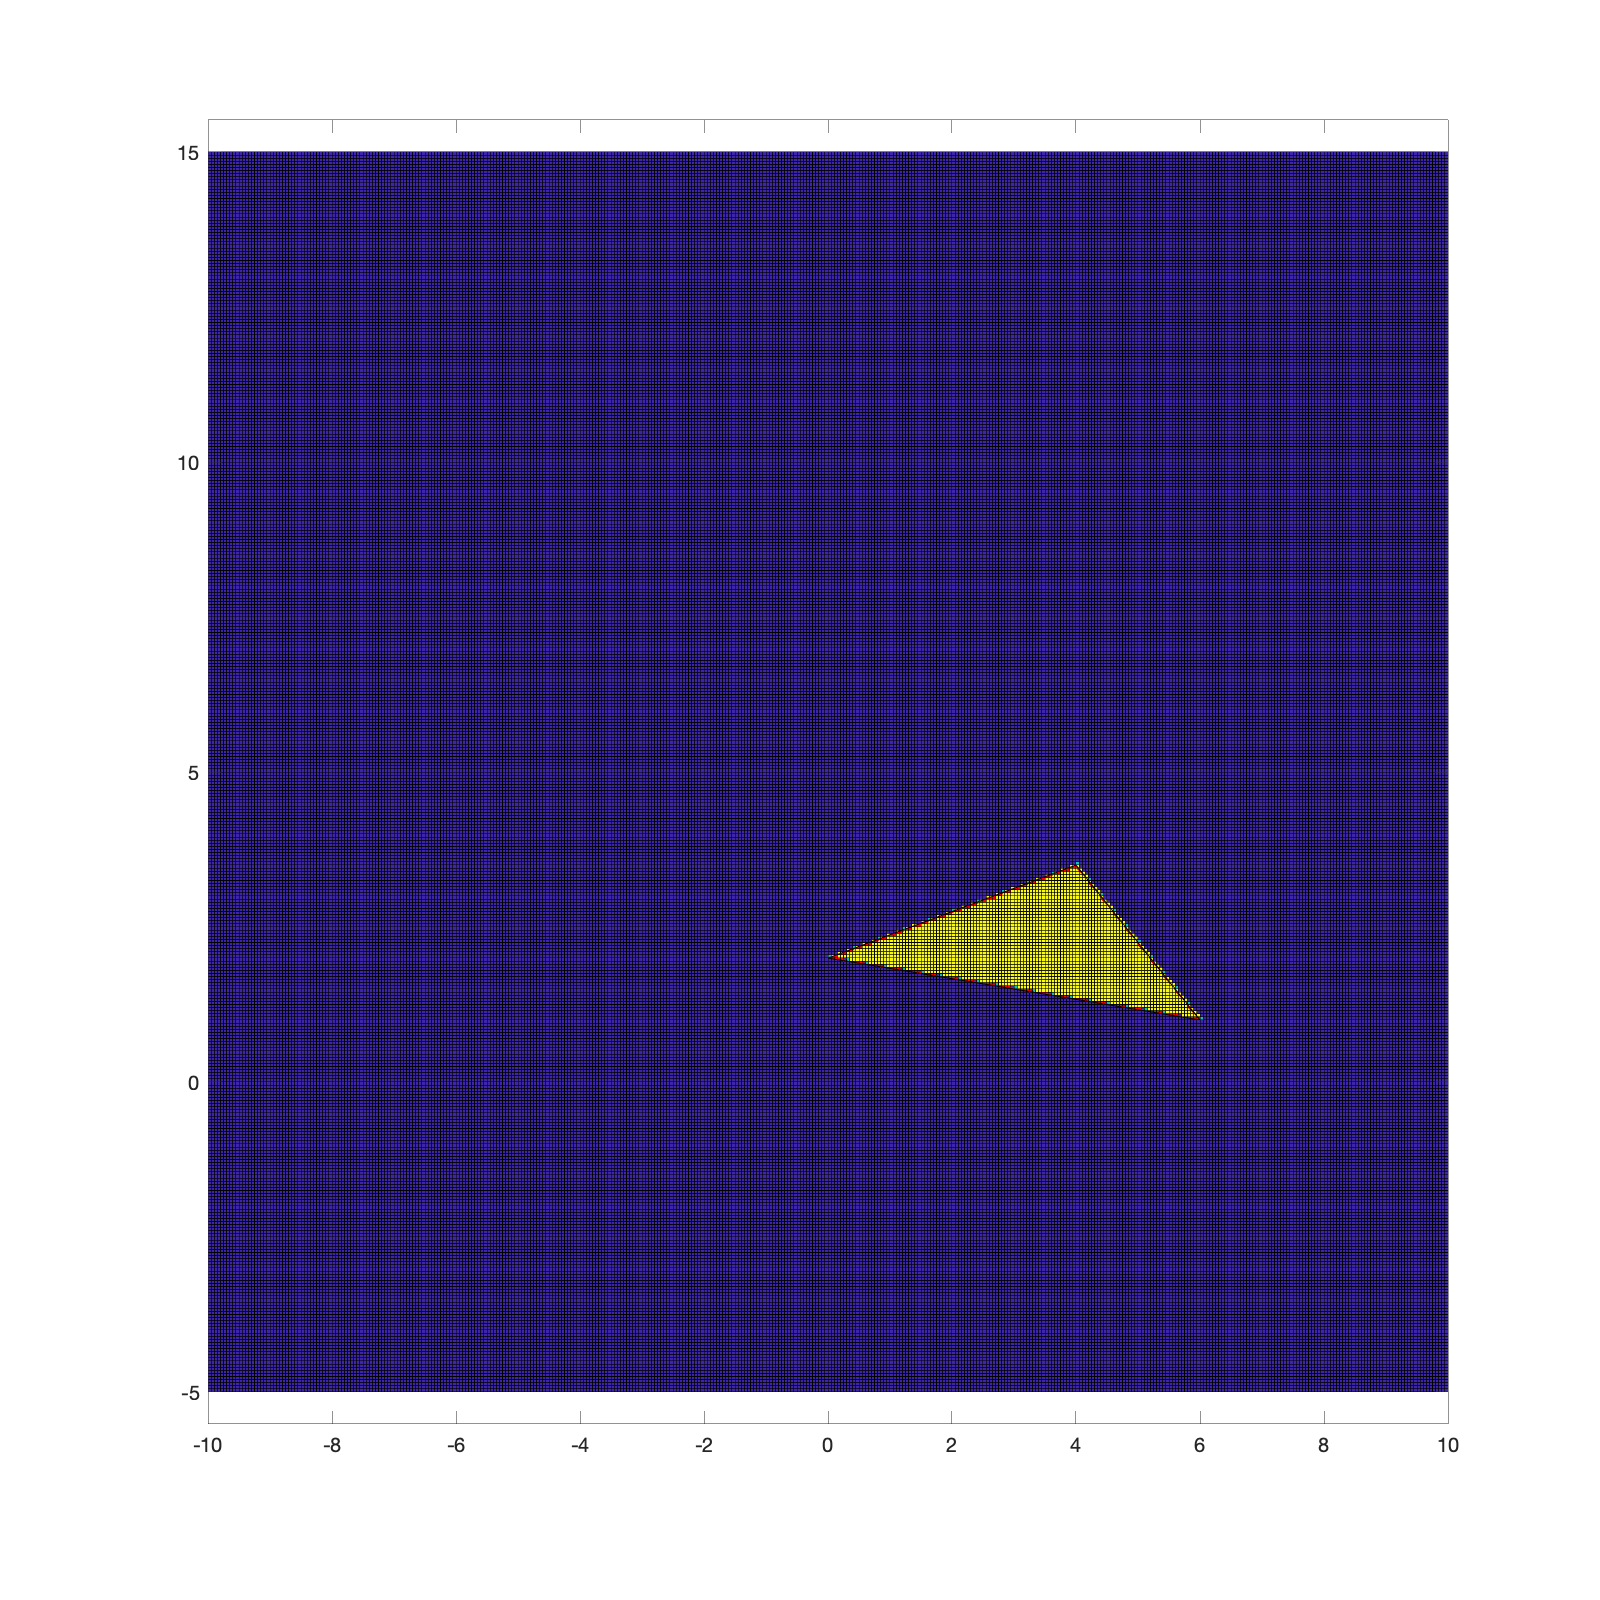


T1.plot('red','Color','white','Linewidth',3);
hold on;

%colormap(hsv);
%contourf(X,Y,Z,40);
surf(X,Y,Z)
axis equal;